clear
clc
close all

- **For Sustained Phonations**

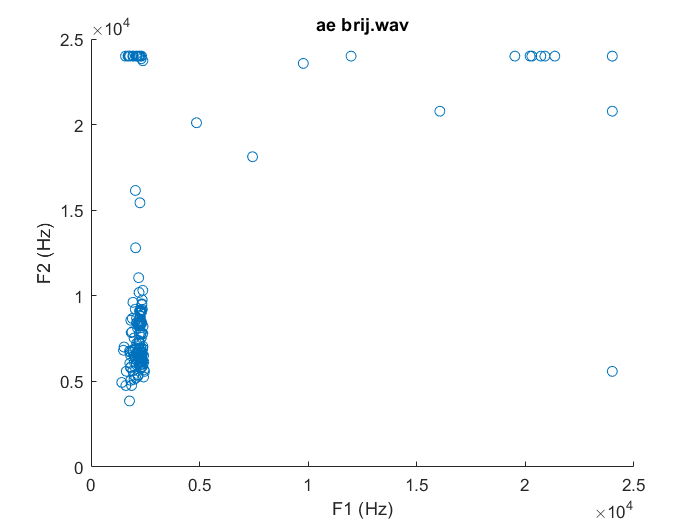

[data_1, fs_1] = audioread("ae_brij.wav");
x_1 = data_1(:,1);
x_1 = resample(x_1,16000,fs_1);

x_1 = x_1(x_1(:,1)>0,:);   % remove zeros, to get only voiced signals
time_1 = (1/fs_1:1/fs_1:length(x_1)/fs_1);

frame_len = ((0.02)*fs_1);    % 20ms frame length      

count = 0; % for loop count    
for j = 1:frame_len:(length(x_1)-frame_len)
    x_ham_1 = x_1(j:j+frame_len-1).*hamming(length(x_1(j:j+frame_len-1)));

    preemph = [1 0.97];
    x_ham_1 = filter(1,preemph,x_ham_1);
    
    A_1 = lpc(x_ham_1,20);
    rts_1 = roots(A_1);
    
    rts_1 = rts_1(imag(rts_1)>=0);
    angz_1 = atan2(imag(rts_1),real(rts_1));
    
    [frqs,indices] = sort(angz_1.*(fs_1/(2*pi)));
    bw = -1/2*(fs_1/(2*pi))*log(abs(rts_1(indices)));
    
    count = count+1;
    t_1(count) = time_1(j+frame_len-1);
    
    num = 1;
    for i = 1:length(frqs)
        if (frqs(i) > 90 && bw(i) <400)
            formant_freqs_1(num) = frqs(i);
            num = num+1;
        end
    end
    F1_F2_formants_1(count,1:2) = formant_freqs_1(1:2); 
end
 
scatter(F1_F2_formants_1(:,1),F1_F2_formants_1(:,2));
title(strcat("ae brij.wav"));
xlabel('F1 (Hz)');
ylabel('F2 (Hz)');

- **For sa1 audio**

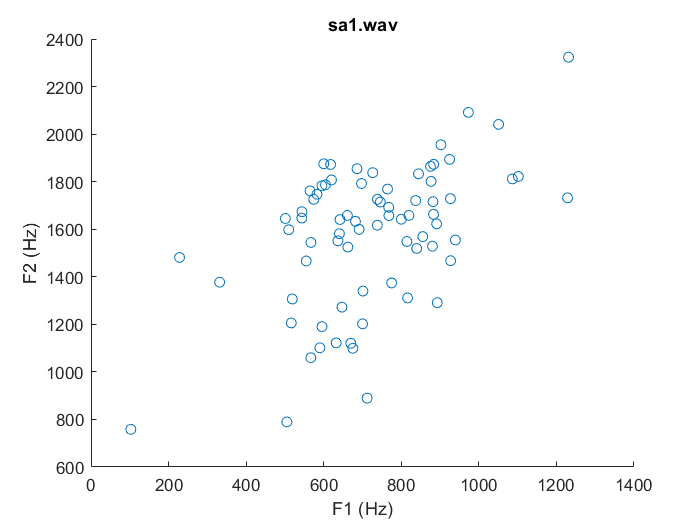


[data, fs] = audioread("sa1.wav");
x = data(:,1);
x = resample(x,16000,fs);

x = x(x(:,1)>0,:);   % remove zeros, to get only voiced signals
time = (1/fs:1/fs:length(x)/fs);

frame_len = ((0.02)*fs);    % 20ms frame length      

count = 0; % for loop count    
for j = 1:frame_len:(length(x)-frame_len)
    x_ham = x(j:j+frame_len-1).*hamming(length(x(j:j+frame_len-1)));

    preemph = [1 0.97];
    x_ham = filter(1,preemph,x_ham);
    
    A = lpc(x_ham,20);
    rts = roots(A);
    
    rts = rts(imag(rts)>=0);
    angz = atan2(imag(rts),real(rts));
    
    [frqs,indices] = sort(angz.*(fs/(2*pi)));
    bw = -1/2*(fs/(2*pi))*log(abs(rts(indices)));
    
    count = count+1;
    t(count) = time(j+frame_len-1);
    
    num = 1;
    for i = 1:length(frqs)
        if (frqs(i) > 90 && bw(i) <400)
            formant_freqs(num) = frqs(i);
            num = num+1;
        end
    end
    F1_F2_formants(count,1:2) = formant_freqs(1:2); 
end
 
scatter(F1_F2_formants(:,1),F1_F2_formants(:,2));
title(strcat("sa1.wav"));
xlabel('F1 (Hz)');
ylabel('F2 (Hz)');

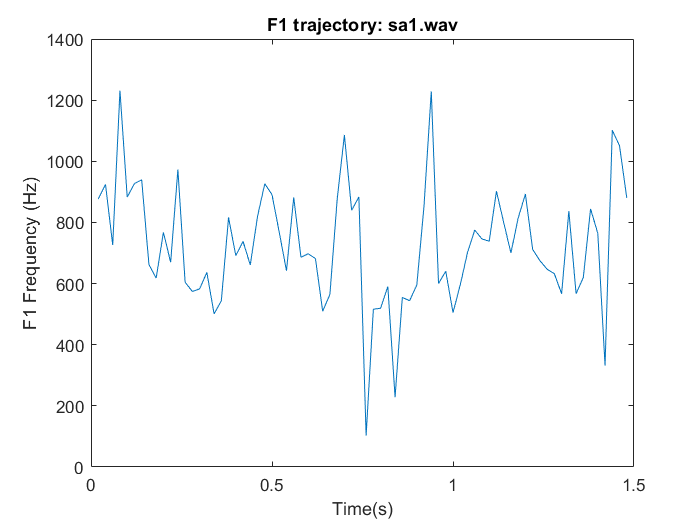


figure
plot(t,F1_F2_formants(:,1))
title(strcat("F1 trajectory: sa1.wav"));
xlabel('Time(s)');
ylabel("F1 Frequency (Hz)");

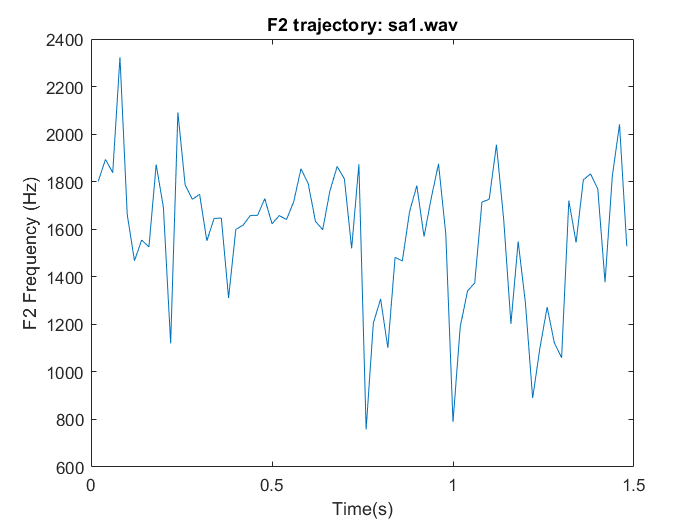


figure
plot(t,F1_F2_formants(:,2))
title(strcat("F2 trajectory: sa1.wav"));
xlabel('Time(s)');
ylabel("F2 Frequency (Hz)");